## Computer Assignment 1

ID:28699490

Shun Iwata

n=3;
X = linspace(1,2.9,n);
Y = f(X);
x = linspace(1,3,100);

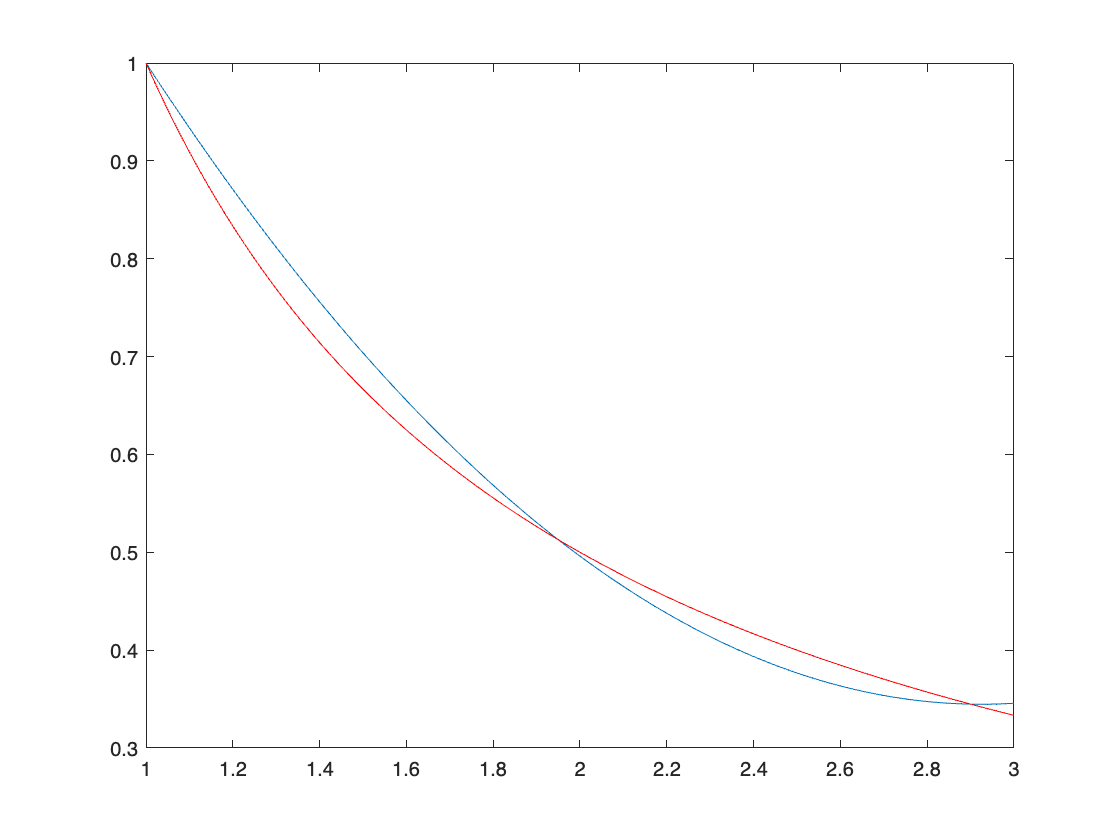

for i = 1:100
xi=x(i);
y(i) = f_lagrange(X,Y,xi);
end
plot(x,y) 
hold on
plot(x,1./x,'-r') 

error=f(3)-f_lagrange(X,Y,3);
error

error = -0.0124

function y=f(x)
y=1./x;
end

function y=f_lagrange(a,b,c)
s=0;
    for i=1:length(a)
    u=1;
    l=1;
     for j=1:length(a)
        if j ~= i
            u = u * (c - a(j));
            l = l * (a(i) - a(j));
        end
     end
    s=s+u/l* b(i);
    end
    y=s;
end